# Homework 3 Math 503B Ashley Jubb

## Using the parameters from Example 1.1 for determining the three parameters defining a ballistic trajectory, construct synthetic examples that demonstrate the following four cases using the SVD. In each case, display and interpret he SVD components U, V and S in terms of the rank, p, of your forward problem G matrix. Display and interpret any model and data null space vector(s) and calculate model and data space resolution matrices.

## a) Three data points that are exactly fit by a unique model. Plot your data points and the predicted model for your model.

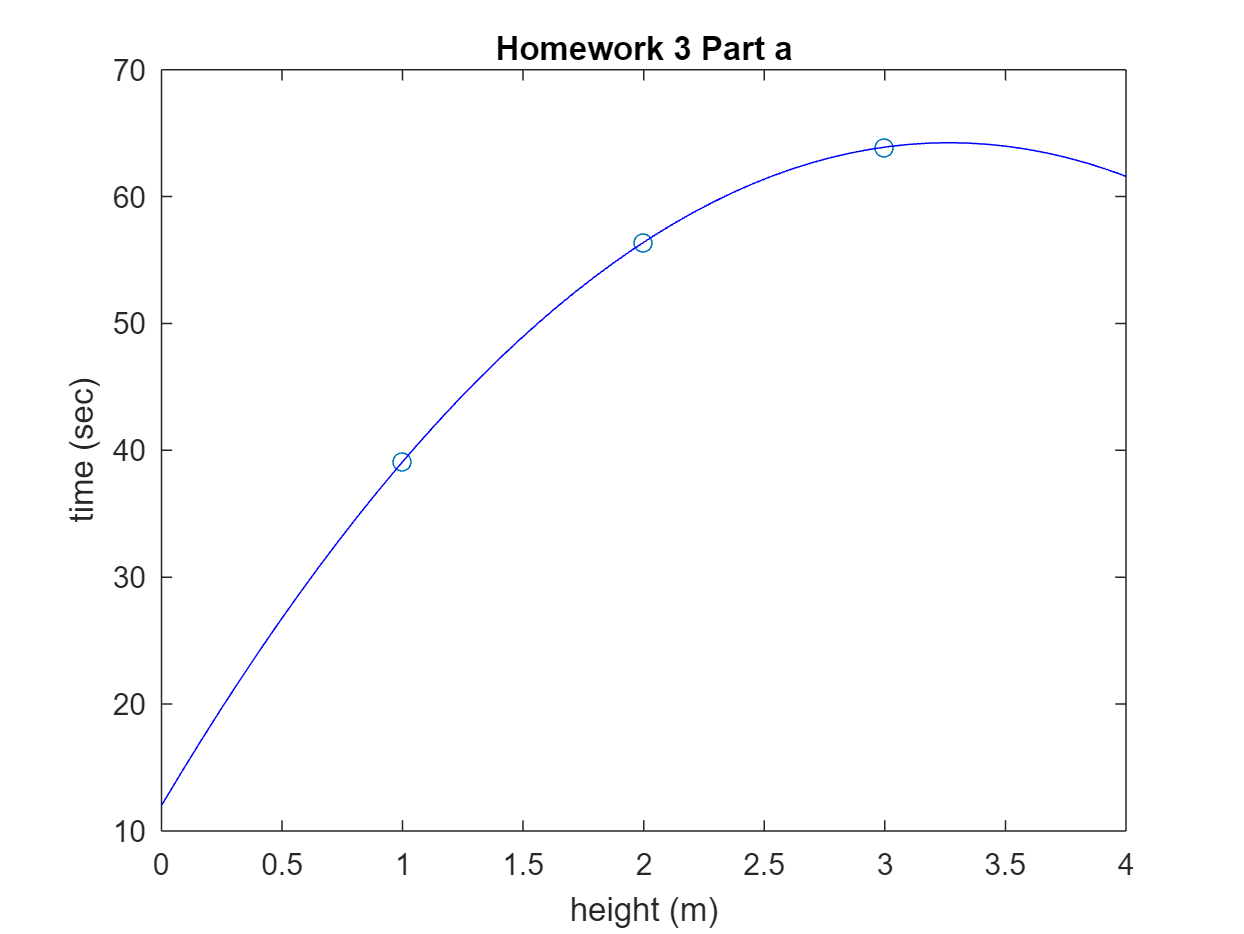

clear;
m_true=[12;32;9.8];
t_obs=linspace(0,4,50);
t_true=[1;2;3];
g=[ones(size(t_true)), t_true, -0.5*t_true.^2];
d=g*m_true;
[U,S,V]=svd(g);
m_obs=(V*inv(S)*transpose(U))*d;
figure(1)
plot(t_true,d,'o')
hold on;
plot(t_obs,m_obs(1)+m_obs(2)*t_obs- 0.5*m_obs(3)*t_obs.^2,'b')
xlabel('height (m)')
ylabel('time (sec)')
title('Homework 3 Part a')

## The model null space and data null space are both trivial.

## b) Two data points that are exactly fit by an infinite suite of parabolas. Plot your data points and the predicted data for a suite of these models.

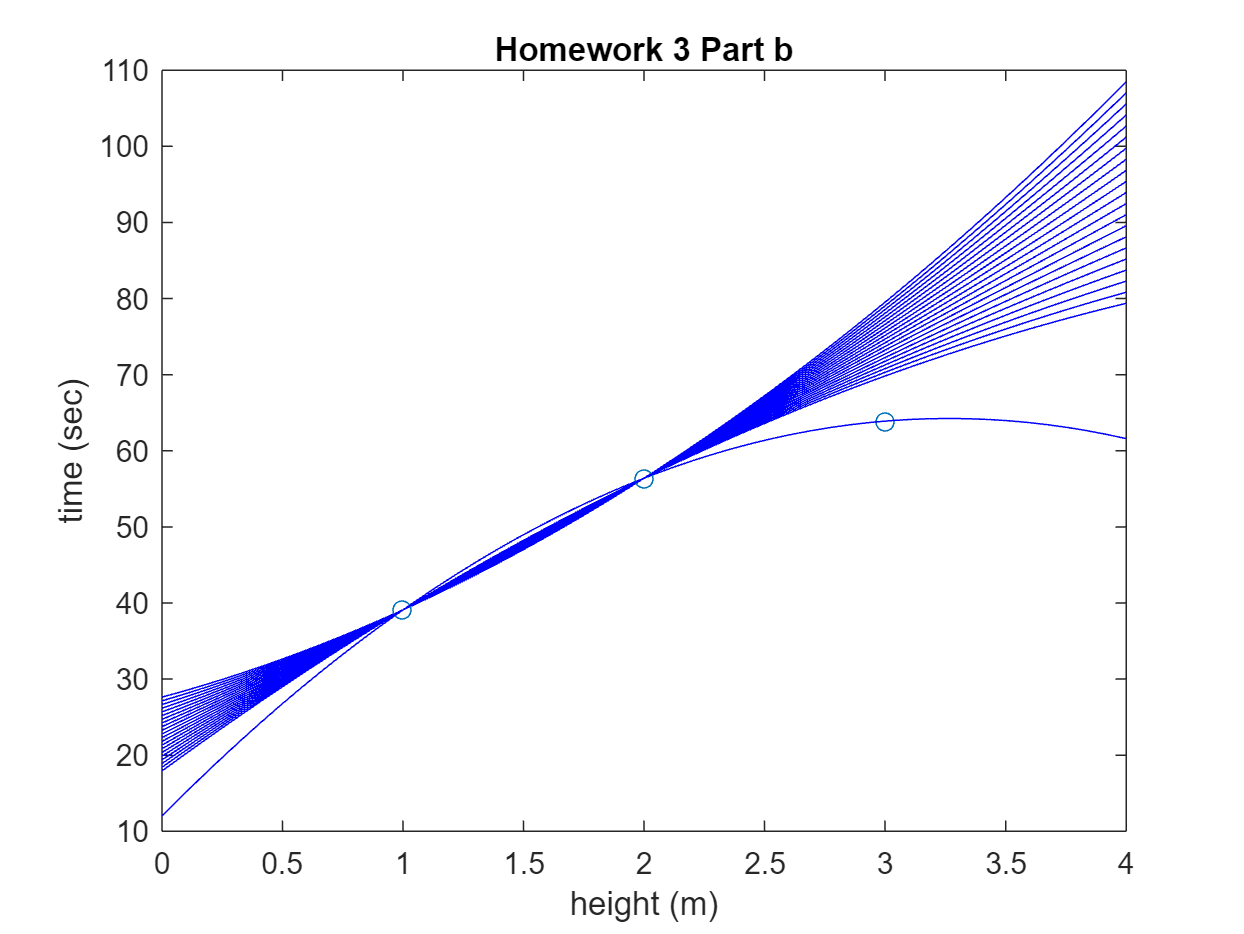

t_true2=[1;2];
g2=[ones(size(t_true2)), t_true2, -0.5*t_true2.^2];
d2=g2*m_true;
[U2,S2,V2]=svd(g2);
p=rank(g2);
m_obs2=(V2(:,1:p)*inv(S2(1:p,1:p))*U2(:,1:p)')*d2;
figure(2)
for i=-10:10
    m=m_obs2+ i*V2(:,3);
    plot(t_true2,d2,'o'); hold on;
    plot(t_obs,m(1)+m(2)*t_obs- 0.5*m(3)*t_obs.^2,'b'); hold on;
end
xlabel('height (m)')
ylabel('time (sec)')
title('Homework 3 Part b')

## The model null space is non-trivial.

## Part c) Four data points that are only approximately fit by a parabola. Plot your data points and the predicted data for the least squares model.

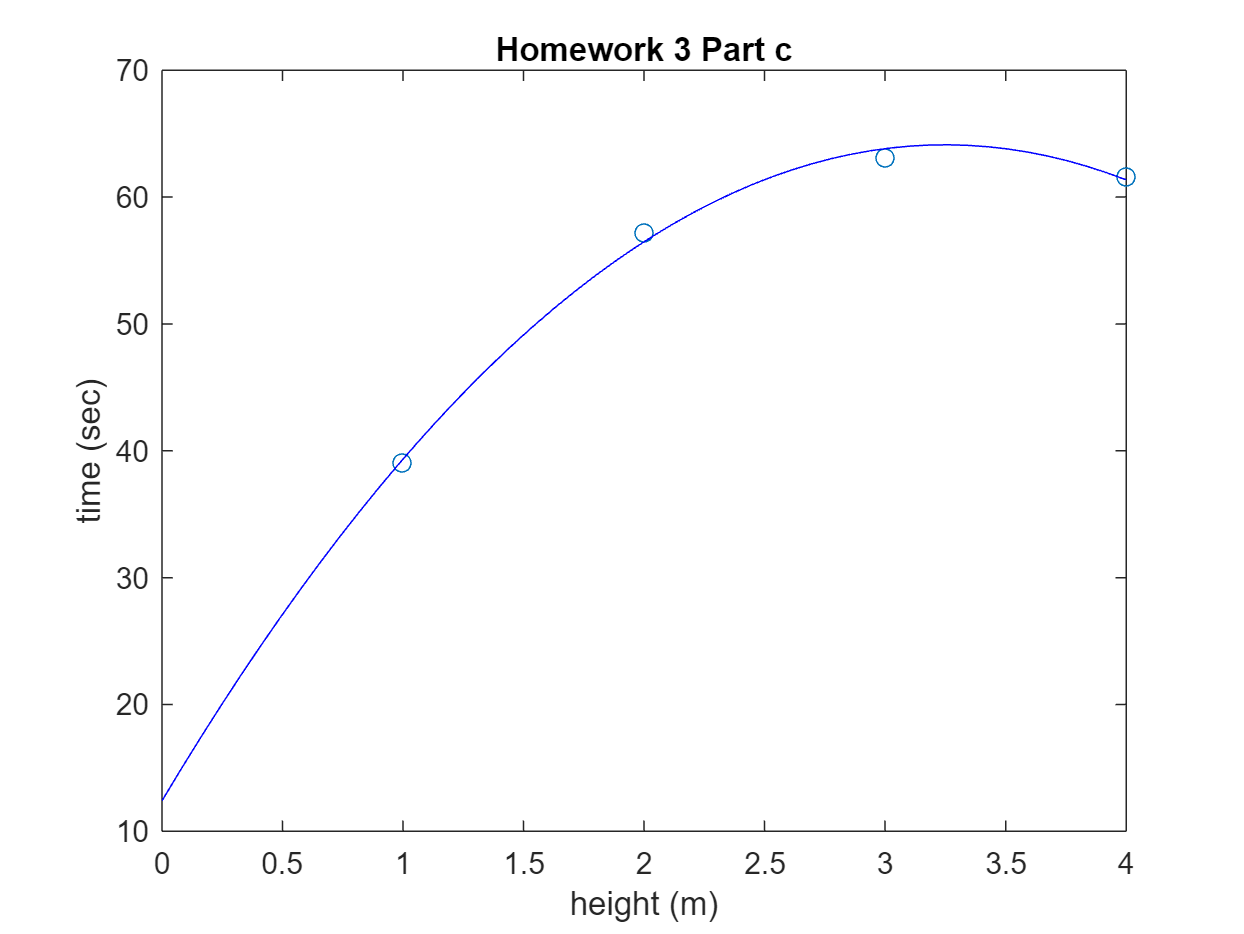

t_true3=[1;2;3;4];
g3=[ones(size(t_true3)), t_true3, -0.5*t_true3.^2];
d3= g3*m_true;
%Alter d3 so it returns an imperfect fit when plotted
d3(2)=d3(2)+0.8;
d3(3)=d3(3)-0.8;
[U3,S3,V3]=svd(g3);
p=rank(g3);
m_obs3=(V3(:,1:p)*inv(S3(1:p,1:p))*U3(:,1:p)')*d3;
figure(3)
plot(t_true3,d3,'o')
hold on;
plot(t_obs,m_obs3(1)+m_obs3(2)*t_obs- 0.5*m_obs3(3)*t_obs.^2,'b')
xlabel('height (m)')
ylabel('time (sec)')
title('Homework 3 Part c')

## The data null space and model null space are non-trivial.

## Part d) Two data points that are only approximately fit to any parabola, and for which there is an infinite number of least square solutions. Plot your data points and the predicted data for a suite of least squares models.

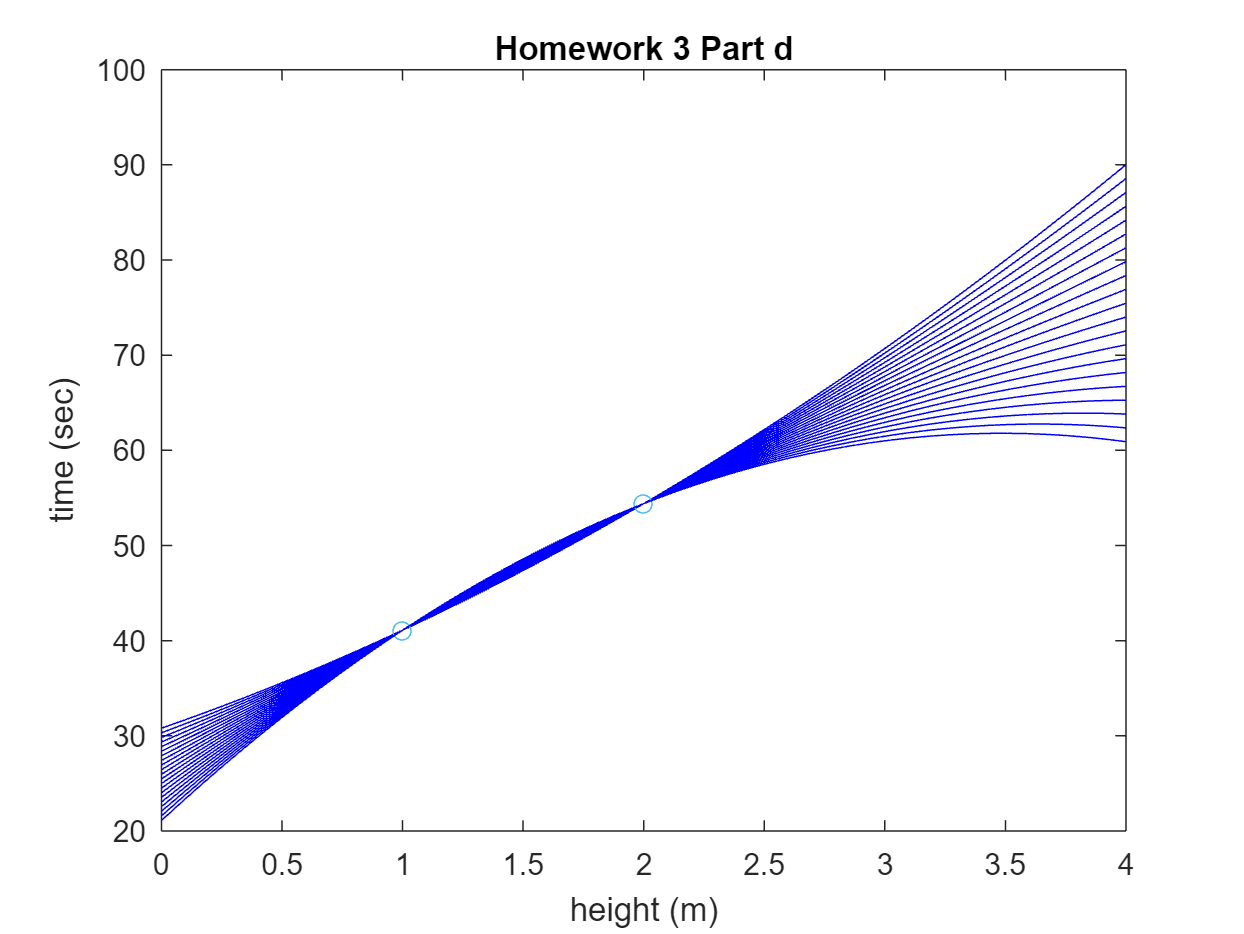

t_true4=[1;2];
g4=[ones(size(t_true4)), t_true4, -0.5*t_true4.^2];
d4=g4*m_true;
d4(1)=d4(1)+2;
d4(2)=d4(2)-2;
[U4,S4,V4]=svd(g4);
p=rank(g4);
m_obs4=(V4(:,1:p)*inv(S4(1:p,1:p))*U4(:,1:p)')*d4;
figure(4)
for i=-10:10
    m=m_obs4+ i*V4(:,3);
    plot(t_true4,d4,'o'); hold on;
    plot(t_obs,m(1)+m(2)*t_obs- 0.5*m(3)*t_obs.^2,'b'); hold on;
end
xlabel('height (m)')
ylabel('time (sec)')
title('Homework 3 Part d')

## The model null space is non-trivial.